# Curvas de comportamiento de COVID 19

**Equipo Alfa Dinamita:**

Israel Cabrera Portilla (188517)

Lorena Patricia Barrera Rodríguez (164694)

Andrea Carolina Padilla Rodríguez (166605)

## Introducción

En esta sección se expone el contexto del problema que se desea solucionar, así como el objetivo a cumplir. Además, se  describe la organización del presente documento.

### Contexto

En computación (y matemáticas), el concepto de «error numérico» es el error en los cálculos numéricos realizados por la computadora. Esto puede suceder debido a dos factores [1]: 

- Error de redondeo: ocurre porque las computadoras usan un número definido de bits para representar números. Entonces, al realizar un cálculo numérico, en cada paso se introducen errores de redondeo; aunque un error de redondeo individual puede ser pequeño, el efecto acumulativo puede resultar significativo. Ciertos tipos de manipulaciones matemáticas son más susceptibles al error de redondeo que otras, como la cancelación sustractiva, productos internos, el aumento en el número de cálculos en un análisis, entre otros.

- Error de truncamiento: se refiere a la diferencia entre la solución matemática exacta y la solución aproximada generada cuando se simplifican las ecuaciones matemáticas para facilitar su cálculo; estas simplificaciones implican el truncamiento de una expansión en serie infinita para hacer posible y práctico el cálculo, o porque se desechan los bits menos significativos de una operación aritmética. Ejemplos de este tipo de error son: aproximación a una derivada usando una ecuación de diferencia finita, series de Taylor, etc.

#### Representación de números en la computadora

De forma predeterminada, MATLAB ha adoptado el formato de doble precisión IEEE Standard 754 en el que se utilizan ocho bytes (64 bits) para representar números de punto flotante: $x={\left(-1\right)}^s *\left(2^{e-1023} \right)*\left(1\ldotp f\right)$ [2], en donde el signo está determinado por un bit de signo, la mantisa $f$ está determinada por un número binario de 52 bits, y el exponente $e$ está determinado por un número binario de 11 bits, del cual se resta 1023 para obtener $e$. 

Aun utilizando este estándar, puede suceder que el resultado de un cálculo aritmético de punto flotante no sea tan preciso como se esperaba; es probable que se deba a las limitaciones del hardware de la computadora del usuario [3]. Es decir, el resultado fue un poco menos exacto porque el hardware no tenía bits suficientes para representar el resultado con precisión finita; por lo tanto, truncó el valor resultante.

### Identificación del problema

El error numérico total es la suma de los errores de truncamiento y redondeo [4]. Aunque agregar dígitos significativos puede mejorar la aproximación, tales cantidades siempre tendrán algún error de redondeo cuando se almacenen en una computadora. Por su parte, el error de truncamiento se puede reducir disminuyendo el tamaño del paso` h.` 

#### Minimización del error de truncamiento

La serie de Taylor predice el valor de una función en un punto en términos del valor de la función y sus derivadas. Matemáticamente:


$$f\left(x_0 \right)=f\left(x_0 \right)+\frac{x-x_0 }{1!}f^{\prime } \left(x_0 \right)+\frac{{\left(x-x_0 \right)}^2 }{2!}f^{\prime \prime } \left(x_0 \right)+\ldotp \ldotp \ldotp +\frac{{\left(x-x_0 \right)}^n }{n!}f^{\left(n\right)} \left(x_0 \right)+R_n$$


En general, la expansión de la serie de Taylor de n-ésimo orden será exacta para un polinomio de n-ésimo orden. En otros casos, la ecuación del término restante $R_n$ se puede expresar como $R_n =O\left(h^{n+1} \right)$, lo que significa que cuantos más términos se utilicen, menor será el error y que  uanto menor sea el espaciado, menor será el error para un número determinado de términos [5]. Sin embargo, debido a que una disminución en el tamaño del paso` h `puede conducir a una cancelación sustractiva o a un aumento en los cálculos, los errores de truncamiento disminuyen a medida que aumentan los errores de redondeo.

La serie de Taylor de primer orden se puede utilizar para calcular aproximaciones a derivadas. Dependiendo de los puntos utilizados, existen aproximaciones de diferencia hacia adelante, diferencia hacia atrás y diferencia centrada.

### Objetivo general

Explorar los errores que presentan diferentes fórmulas de derivación numérica: las aproximaciones centradas, hacia adelante y hacia atrás de la primera y segunda derivada, $O\left(h\right)$ y $O\left(h^2 \right)$. 

### Organización del documento

El documento está estructurado de la siguiente manera:

- **Sección 1: Introducción**. Se describe el contexto, el problema a resolver y el objetivo general del proyecto.

- **Sección 2: Análisis**. Se especifican los requerimientos funcionales y no funcionales de la solución, así como sus restricciones.

- **Sección 3: Desarrollo**. Se exponen detalladamente las funciones desarrolladas que pretenden cumplir con el objetivo del proyecto (esta sección corresponde a Anexo: Funciones).

- **Sección 4: Pruebas y Resultados**. Se presentan las pruebas llevadas a cabo con el fin de evaluar el cumplimiento de los requerimientos y explorar los errores obtenidos de las funciones de aproximación.

- **Sección 5: Conclusiones**. Se evalúa el desempeño general del proyecto en relación con  el  objetivo  y  el  problema  a  resolver.  Además,  se  explican  posibles  mejoras  y propuestas de trabajos futuros para profundizar la solución.

## Análisis

En esta sección se describen las funcionalidades generales que debe cumplir la solución, así como las restricciones para su desarrollo.

### Requerimientos

#### Funcionales

- El sistema debe calcular las aproximaciones centradas, hacia adelante y hacia atrás de la primera y segunda derivada de las funciones en el punto dado. 

- El sistema debe soportar diferentes funciones: polinomiales, trigonométricas, entre otras. 

- El número de veces que se realiza la aproximación debe poder ser modificado para observar el comportamiento del error. 

- El sistema debe mostrar recursos gráficos como ayuda a la evaluación de los errores y visualización de su comportamiento.

#### No funcionales

- En caso de error, el sistema debe informar al usuario de manera clara cuál fue dicho error.

- En caso de que las derivadas se la función sean` 0 `o constantes, el sistema debe mostrar un mensaje de advertencia al usuario.

- El código debe ser documentado adecuadamente siguiendo las convenciones de código (nombres de variables y funciones, sangría y espaciado, entre otros).

- Los recursos gráficos deben contener los elementos necesarios para facilitar su interpretación (título del gráfico, título de los ejes, cuadrícula, entre otros).

### Restricciones

- Las funciones a derivar deben ser continuas y de una sola variable.

- El sistema sólo calculará las aproximaciones centradas, hacia adelante y hacia atrás de la primera y segunda derivada de primer y segundo orden. Es decir, no podrá realizar a partir de la tercer derivada de ninguna función, ni ejecutará los cálculos para obtener nignuna derivada de tercer orden.

## Pruebas y resultados

En esta sección se muestran las pruebas realizadas para determinar la eficiencia de los algoritmos de aproximación dependiendo de la` h `utilizada para calcular las derivadas. También, se muestran los errores obtenidos de las aproximaciones y su gráfica correspondiente.

Para verificar que los métodos cumplan con todos los requisitos del problema observando criterios de corrección, integridad, eficiencia y robustez, se utilizaron arbitrariamente las siguientes funciones y puntos:

- $f\left(x\right)=-0\ldotp 1x^4 -0\ldotp 15x^3 -0\ldotp 5x^2 -0\ldotp 25x+1\ldotp 2$, `x = 0.5`. Esta función polinomial es continua y doblemente diferenciable en el punto dado.

- $f\left(x\right)=\frac{\sin \left(x^2 \right)}{x^2 }$, `x = 2.5`. Esta función trigonométrica es continua y doblemente diferenciable en el punto dado.

- $f\left(x\right)=2x+6$ , `x = 1.75`. La primera derivada de esta función es una constante, por lo que su segunda derivada es` 0`. Con esta función se pretende evaluar la robustez de los algoritmos programados.

- $f\left(\right)=2x^3 -\frac{\sqrt{\Pi }}{x}+2$.  Esta función, aunque polinomial, no cuenta con argumentos de entrada, por lo que se deberá mostrar el correspondiente mensaje de error.

### titulo

M = [3, -2 ; 2, -2];
t0 = 0;
yz0 = [1 ; -1];
tf = 2;
h = 0.1;
f = @(t, yz) M * yz;
[t, yz] = odeRK4(f, yz0, t0, tf, h);
plot(t, yz);
xlabel('t');
legend('y', 'z');
grid on;

data = readtable('COVID-NL.csv')

data = 30×7 table
        Fecha         Susceptibles    Expuestos    Confirmados    Recuperados    Defunciones    Activos
    ______________    ____________    _________    ___________    ___________    ___________    _______

    {'01-06-2021'}     5.6102e+06        398       1.7866e+05     1.6617e+05        10859        1640  
    {'02-06-2021'}     5.6102e+06        401       1.7878e+05     1.6631e+05        10868        1607  
    {'03-06-2021'}     5.6102e+06        397        1.789e+05     1.6646e+05        10876        1562  
    {'04-06-2021'}     5.6102e+06        392       1.7903e+05     1.6662e+05        10883        1522  
    {'05-06-2021'}     5.6102e+06        396       1.7915e+05     1.6668e+05        10892        1575  
    {'06-06-202

S = table2array(data(:, "Susceptibles"));
E = table2array(data(:, "Expuestos"));
I = table2array(data(:, "Activos"));
R = table2array(data(:, "Recuperados"));

y0 = [8112504 ; 7 ; 7 ; 0];
% y0 = [S(1) ; I(1) ; R(1)];
t0 = 1;
tFin = 30;
h = 0.01;

[t, y] = ode45(@seir, t0:h:tFin, y0)

t =     1.0000
    1.0100
    1.0200
    1.0300
    1.0400
    1.0500
    1.0600
    1.0700
    1.0800
    1.0900


y = 	1.0e+06 *

    8.1125    0.0000    0.0000         0
    0.0000    8.0878    0.0246    0.0001
    0.0000    8.0542    0.0580    0.0003
   -0.0000    8.0207    0.0910    0.0009
   -0.0000    7.9873    0.1236    0.0016
    0.0000    7.9540    0.1559    0.0026
    0.0000    7.9209    0.1878    0.0038
   -0.0000    7.8880    0.2194    0.0052
    0.0000    7.8552    0.2506    0.0068
   -0.0000    7.8225    0.2814    0.0086


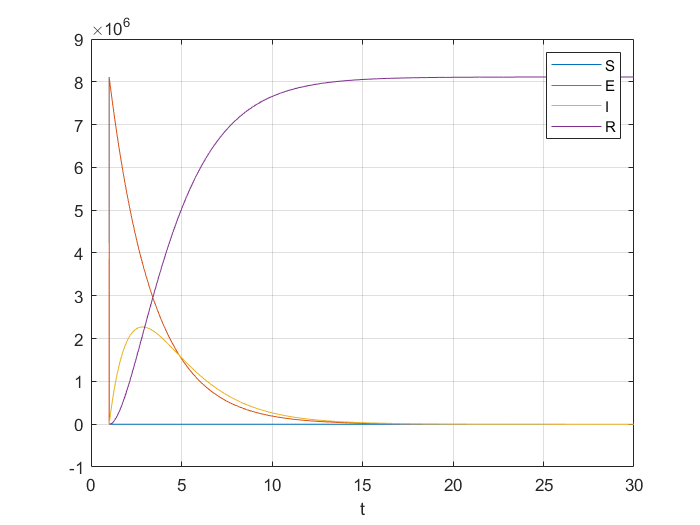

plot(t, y);
xlabel('t')
legend({'S', 'E', 'I', 'R'});
grid on;

% [t, y] = odeRK4(@sir, y0, 1, 30, 1)

## Conclusiones

En la función polinomial, para la primera derivada, la fórmula de aproximación centrada tiene el mejor desempeño; es decir, es la que tiene menos errores. Análogamente, para la segunda derivada, esta aproximación tiene un mejor desempeño ya que alcanza el mínimo más rápido. Para la función trigonométrica, en la primera derivada se nota una tendencia parecida a la de la primera función; es decir, la fórmula con menos errores es la de aproximación centrada. Para su segunda derivada, la aproximación central de segundo orden también tuvo el mejor desempeño. Aunque se haya visto una tendencia en las funciones anteriores, en la tercera función, donde la derivada tiene como resultado una constante, se obtuvo que es trivial elegir entre las aproximaciones de hacia adelante de primer orden, hacia atrás de primer orden y centrada de segundo orden, ya que tienen los mismo valores para la primera derivada; para la segunda derivada no es posible comparar las gráficas, pero de los valores de la tabla se concluye que la aproximación centrada es la más eficiente porque no hay ningún error.  

El sistema programado utiliza un valor h que se refiere al tamaño del paso que transcurre dentro de la función e influye en el error obtenido. Como se pudo observar en las gráficas de los resultados, existe un valor específico en el que el error numérico total es mínimo y es cuando el error de truncamiento y el error de redondeo son mínimos. Por lo tanto, si el valor de h disminuye más de ese punto, el valor del error de redondeo empieza a incrementar porque la computadora no tiene la capacidad de representar valores tan pequeños y específicos. Por otro lado, si el valor de h incrementa más del punto óptimo, el valor del error de truncamiento empieza a aumentar debido a que se usan menos dígitos significativos, es decir que se vuelven muy generales. Sin embargo, aún minimizando el error numérico total, puede suceder que el resultado no sea tan preciso como se esperaba; tal como se mencionó en la introducción, es probable que se deba a las limitaciones del hardware de la computadora del usuario.

## Referencias

[1] R. Fitzpatrick, «Numerical errors,» 29 Marzo 2006. [En línea]. Disponible en: http://farside.ph.utexas.edu/teaching/329/lectures/node33.html. [Último acceso: 25 Junio 2021].

[2] M. Mejía Olvera, «Computer Numbers: Fun with IEEE 754,» 17 Junio 2021. [En línea]. Disponible en: https://itam.instructure.com/courses/3332/assignments/40962?module_item_id=101786. [Último acceso: 25 Junio 2021].

[3] The MathWorks, Inc., «Floating-Point Numbers,» 1994-2021. [En línea]. Disponible en: https://la.mathworks.com/help/matlab/matlab_prog/floating-point-numbers.html. [Último acceso: 27 Junio 2021].

[4] S. C. Chapra, «Total numerical error,» de *Applied Numerical Methods with MATLAB® for Engineers and Scientists*, Tercera ed., New York, McGraw-Hill, 2012, pp. 114-119.

[5] D. López, C. Álvarez y Y. Ceballos, «Series de Taylor y errores de truncamiento,» 30 Abril 2016. [En línea]. Disponible en: https://aprendeenlinea.udea.edu.co/lms/moodle/mod/page/view.php?id=24480. [Último acceso: 26 Junio 2021].

## Anexo: Funciones

### Funciones auxiliares

function [t, y] = odeRK4(f, y0, t0, tFin, h)
    t = t0:h:tFin;
    n = length(t);
    y = zeros(length(y0), n);
    y(:, 1) = y0;
    
    for i = 1:n-1
        k1 = f(t(i), y(:, i));
        k2 = f(t(i) + h/2, y(:, i) + k1 * h/2);
        k3 = f(t(i) + h/2, y(:, i) + k2 * h/2);
        k4 = f(t(i) + h, y(:, i) + k3 * h);
        phi = (k1 + 2 * k2 + 2 * k3 + k4) / 6;
        y(:, i + 1) = y(:, i) + phi * h;
    end
end


function dxdt = si(~, x)
    beta = 1.33;
    dxdt = zeros(2, 1);
    dxdt(1) = -beta * x(1) * x(2);
    dxdt(2) = beta * x(1) * x(2);
end


function dxdt = sis(~, x)
    beta = 1.33;
    gamma = 0.69;
    dxdt = zeros(2, 1);
    dxdt(1) = -beta * x(1) * x(2) + gamma * x(2);
    dxdt(2) = beta * x(1) * x(2) - gamma * x(2);
end


function dxdt = sir(~, x)
    beta = 1.33;
    gamma = 0.69;
    dxdt = zeros(3, 1);
    dxdt(1) = -beta * x(1) * x(2);
    dxdt(2) = beta * x(1) * x(2) - gamma * x(2);
    dxdt(3) = gamma * x(2);
end


function dxdt = seir(~, x)
    beta = 1.33;
    gamma = 0.69;
    eta = 0.417;
    dxdt = zeros(4, 1);
    dxdt(1) = -beta * x(1) * x(3);
    dxdt(2) = beta * x(1) * x(3) - eta * x(2);
    dxdt(3) = eta * x(2) - gamma * x(3);
    dxdt(4) = gamma * x(3);
end